# Classification - TSK Models

## Problem Description

In this project, we are tasked with implementing TSK (Takagi-Sugeno-Kang) fuzzy systems, solving classification problems. 

This project is two fold. First we are given a simple dataset called 'haberman'. We then will be training 4 specific models with different configurations and evaluating their performance. Specifically, we will test the combinations below, in which we test the contribution of two parameters in the model's performance, the class dependency and the cluster's radius. We want to also see, how the number of rules is affected by each modification.

Models = {'Model 1'; 'Model 2'; 'Model 3'; 'Model 4'};
Class_Dependance = {'Independent'; 'Independent'; 'Dependent'; 'Dependent'};
Radius = {'0.2';'0.9'; '0.2'; '0.9'};
Combinations_Table = table(Models, Class_Dependance, Radius);
disp(Combinations_Table);

      Models       Class_Dependance    Radius 
    ___________    ________________    _______

    {'Model 1'}    {'Independent'}     {'0.2'}
    {'Model 2'}    {'Independent'}     {'0.9'}
    {'Model 3'}    {'Dependent'  }     {'0.2'}
    {'Model 4'}    {'Dependent'  }     {'0.9'}



The second part, includes a more complex, high-dimensional dataset '*epileptic_seizure_data*'. Given its nature, before implementing any model, we are required to reduce its dimensions and fuzzy set of rules. We will then train the model, and assess its performance.

For both implementations, we will split the datasets in a 60-20-20 ratio for training-validating-checking. Each model's performace, learning curve and prediction errors will be visualised and analysed.

## TSK Application on Simple Dataset

### Haberman Dataset Overview

In this first section, we will utilize the 'Haberman' dataset, which consists of 306 instances, each with 3 features and one output. 

Specifically:

Input:

- Age; Age of patient

- Year; Year of operation to remove nodes

- Nodes; Number of positive auxillary nodes detected

Output:

- Survival Status; Status of the person (1: lived 5 or more years, 2: died within 5 years)

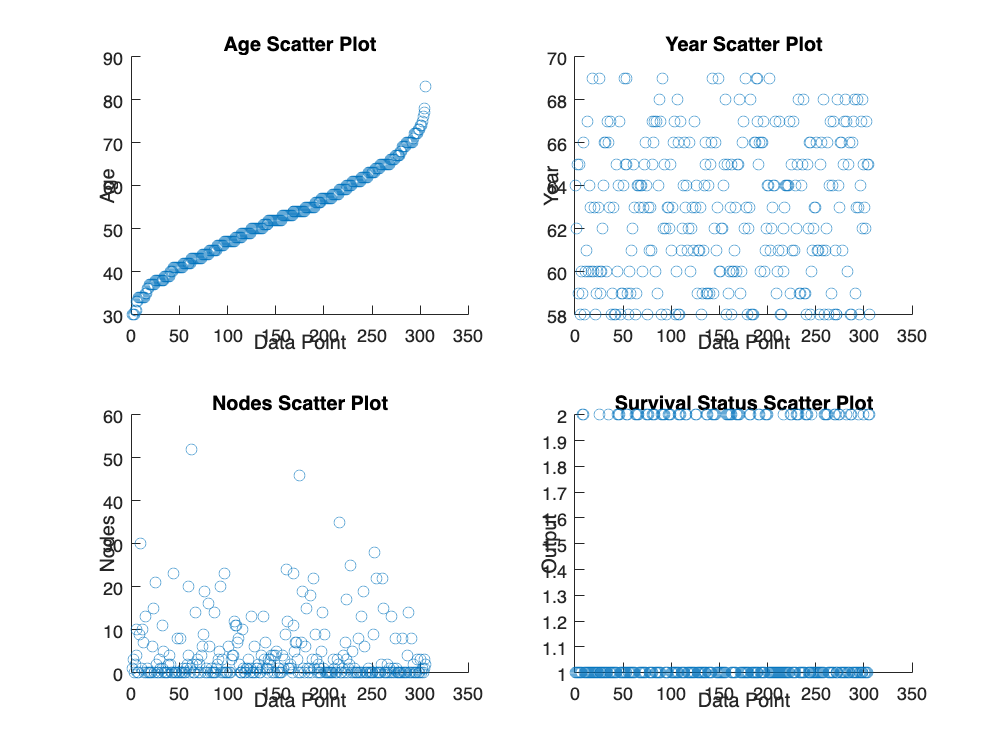

clc; clearvars; close all;
warning('off','all')
addpath("lib")
addpath("lib/datasets")
data_1 = table2array(readtable('datasets/haberman.data', 'FileType', 'text'));

% Visualize Data
feature_names_1 = {'Age', 'Year', 'Nodes', 'Survival Status'};
visualize_data(data_1, feature_names_1, 1:3);

[Dtrn_1, Dval_1, Dchk_1] = split_data(data_1);

Dimensions of Training Data:
   184     4

Dimensions of Validation Data:
    61     4

Dimensions of Checking Data:
    61     4



### TSK Model 1

We will begin with implementing the first model, according the the requirements.

% Define configuration for Model 1
model_1 = struct('Type', 'Independent', 'Radius', 0.2);

initial_fis_1 = initialize_tsk_model(Dtrn_1, model_1);

initial_fis =   sugfis with properties:

                       Name: "sug31"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×26 fisrule]

	See 'getTunableSettings' method for parameter optimization.


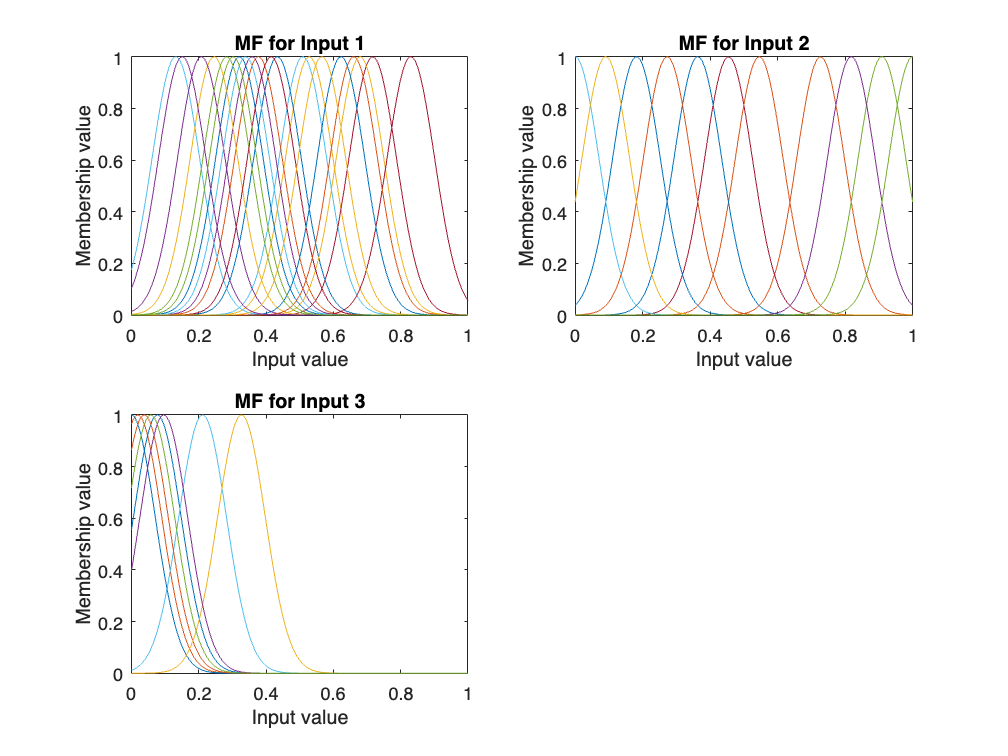

plot_mf(initial_fis_1, 3);

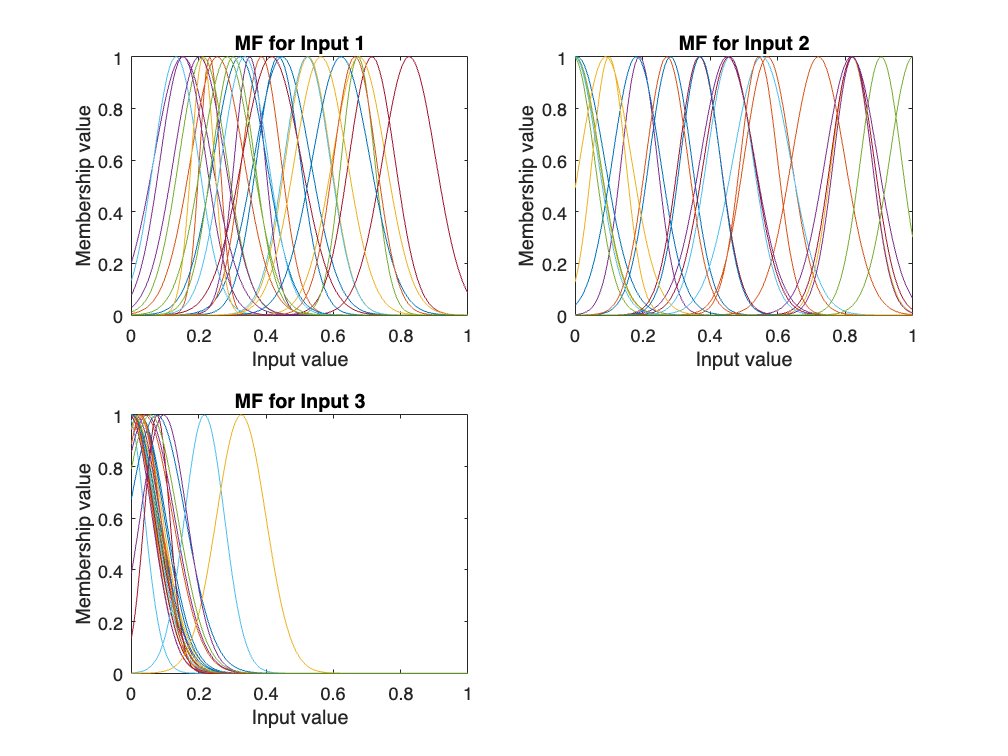

% Train Model 1
tic;
[trained_fis_1, training_info_1] = train_tsk_model(initial_fis_1, Dtrn_1, Dval_1, 100);
time_1 = toc;
plot_mf(trained_fis_1, 3);

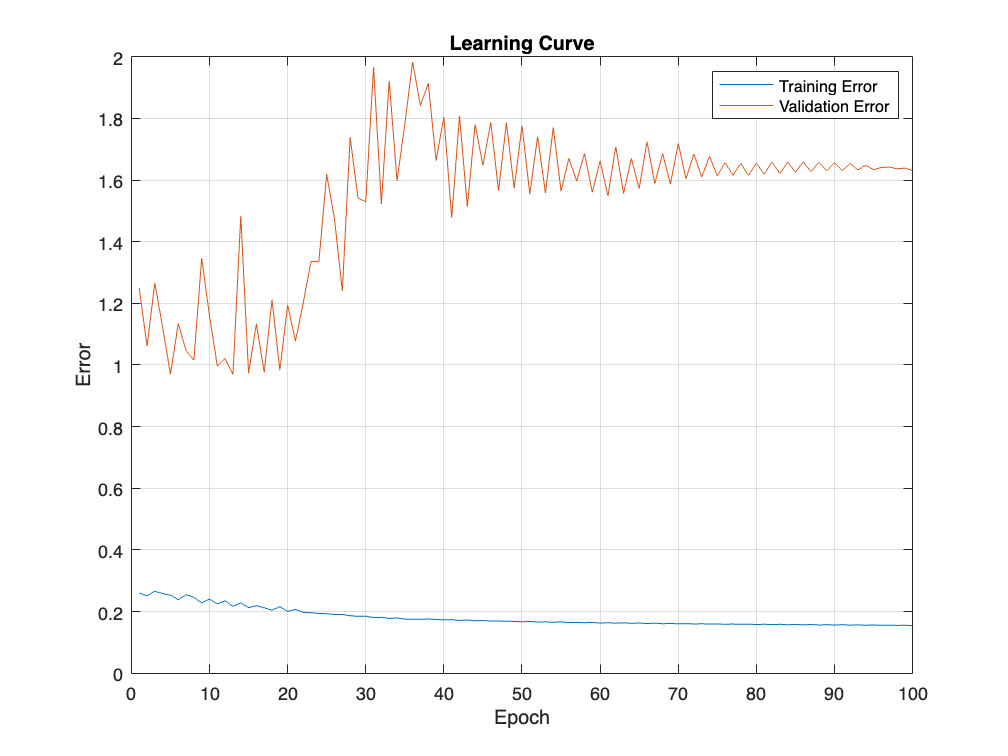

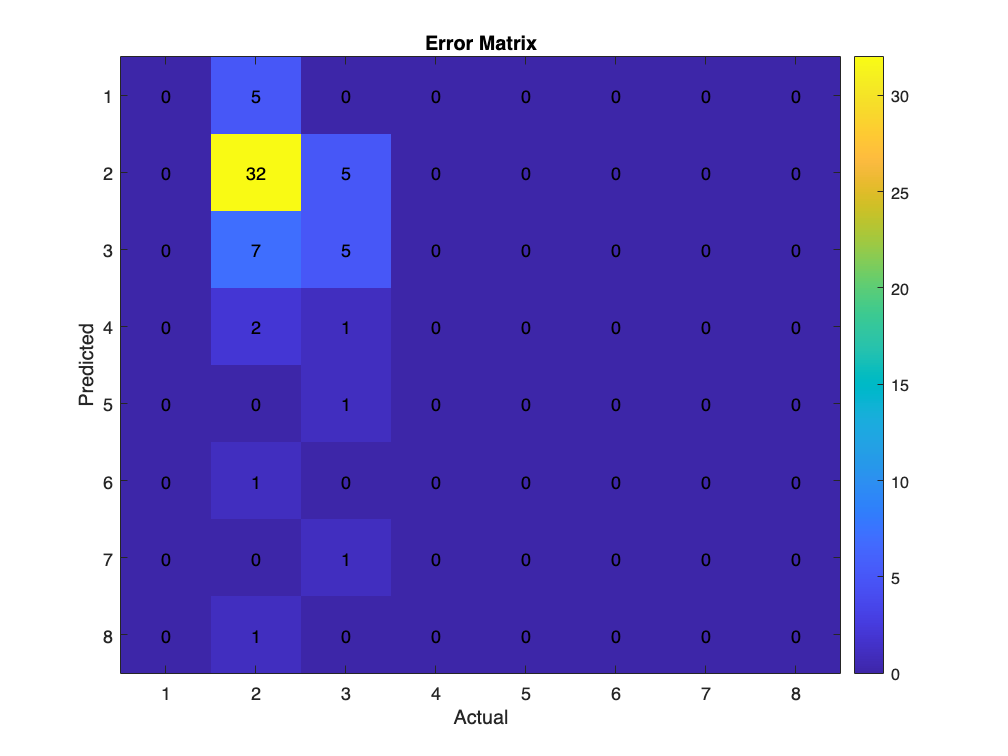

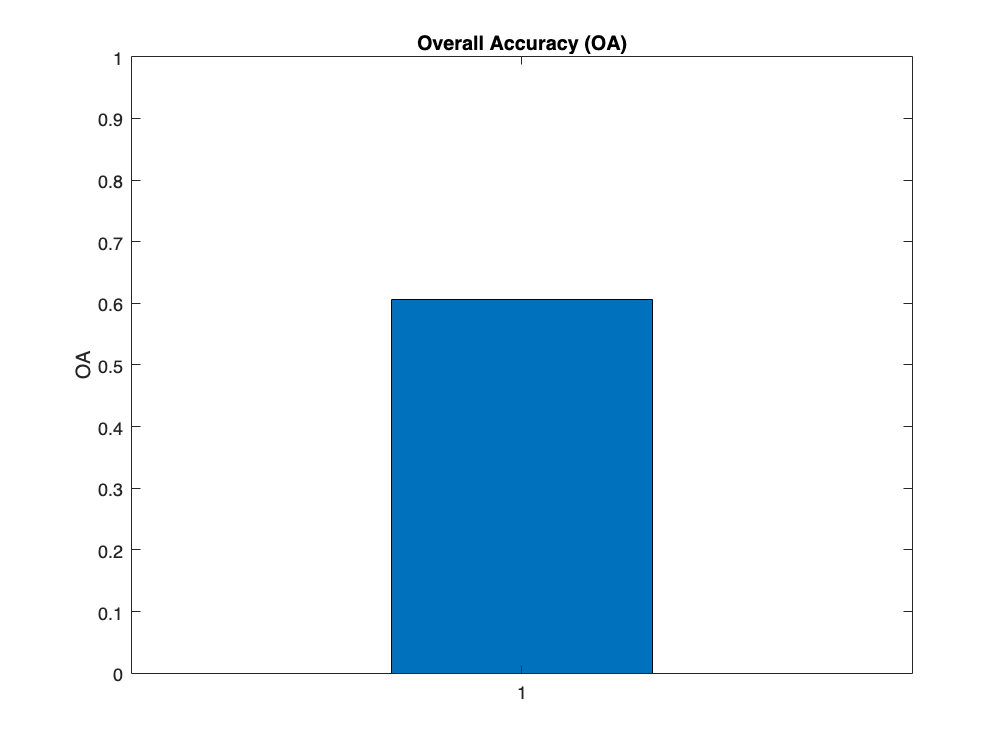

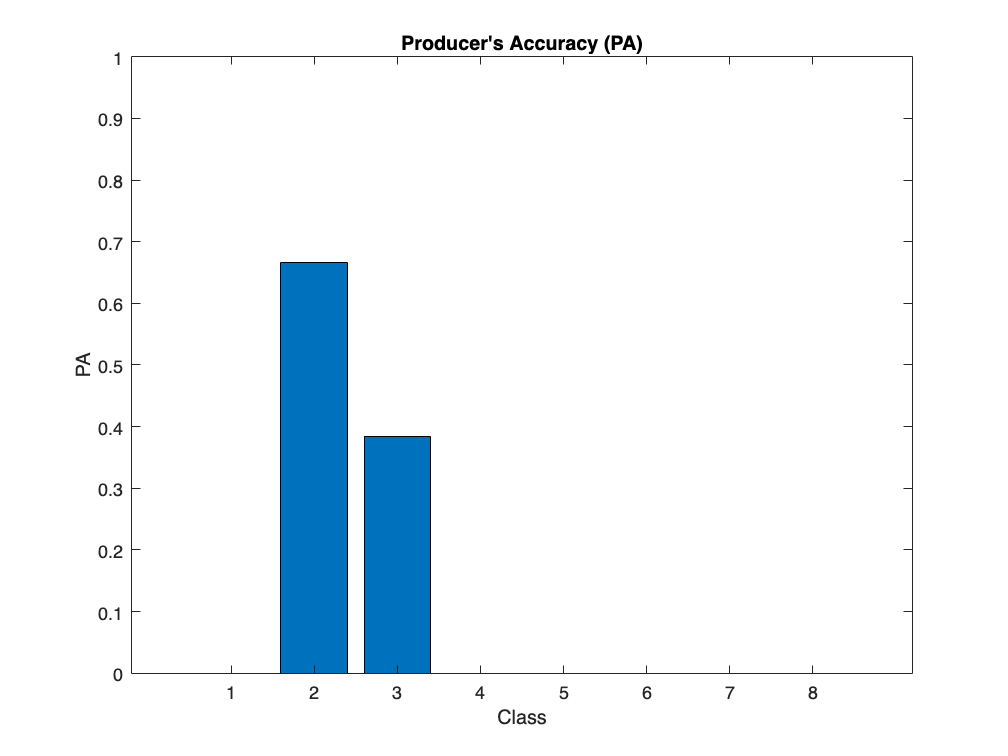

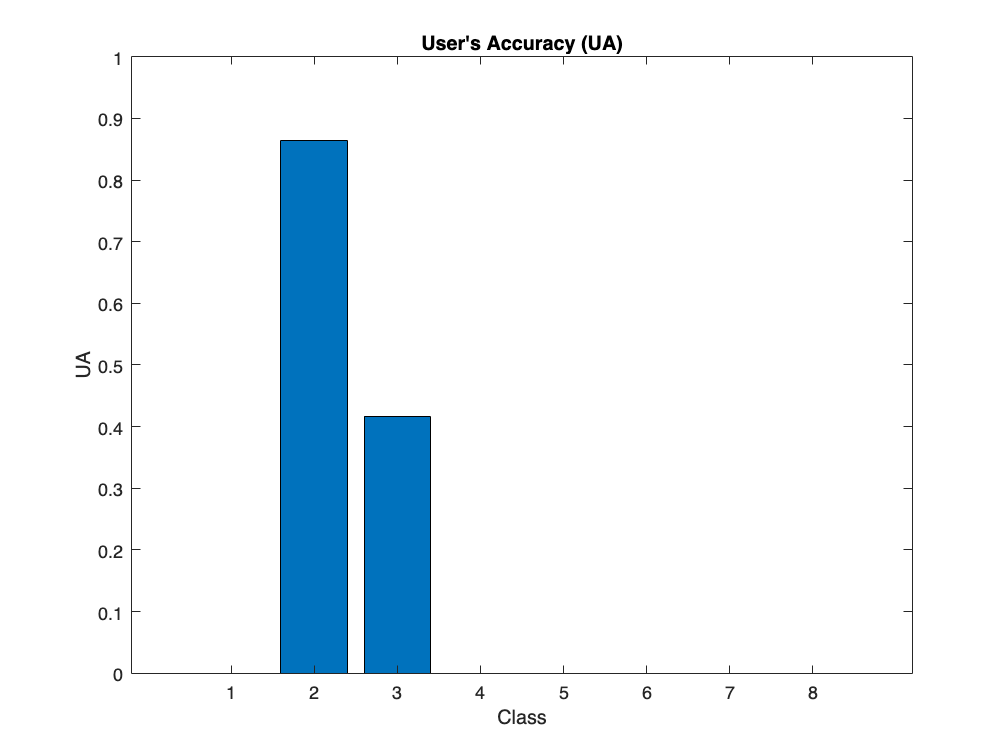

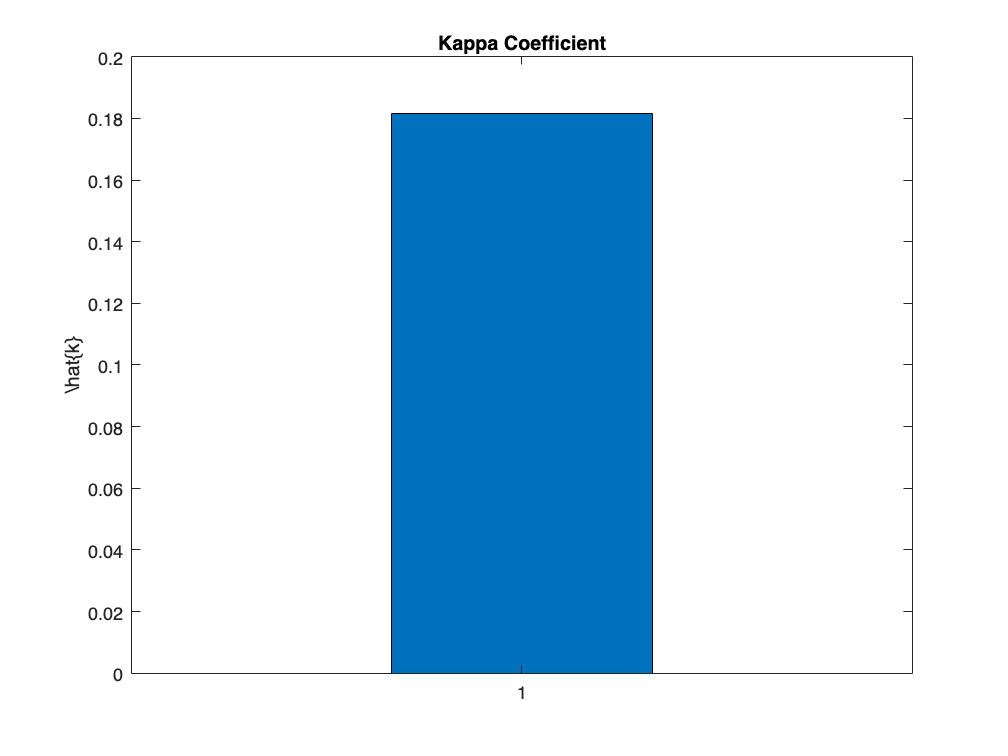

% Evaluate Model 1
[error_matrix, OA, PA, UA, kappa] = metrics_evaluation(trained_fis_1, Dchk_1);
plot_metrics(error_matrix, OA, PA, UA, kappa, training_info_1.trainError, training_info_1.chkError);

model_1_metrics = [OA; max(PA); max(UA); kappa; length(trained_fis_1.Rules)];
fprintf('Classification metrics for the model:\n OA: %.4f, PA: %.4f, UA: %.4f, Kappa: %.4f\n', OA, max(PA), max(UA), kappa);

Classification metrics for the model:
 OA: 0.6066, PA: 0.6667, UA: 0.8649, Kappa: 0.1817


### TSK Model 2

We will continue implementing the second model.

% Define configuration for Model 2
model_2 = struct('Type', 'Independent', 'Radius', 0.9);

initial_fis_2 = initialize_tsk_model(Dtrn_1, model_2);

initial_fis =   sugfis with properties:

                       Name: "sug31"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×2 fisrule]

	See 'getTunableSettings' method for parameter optimization.


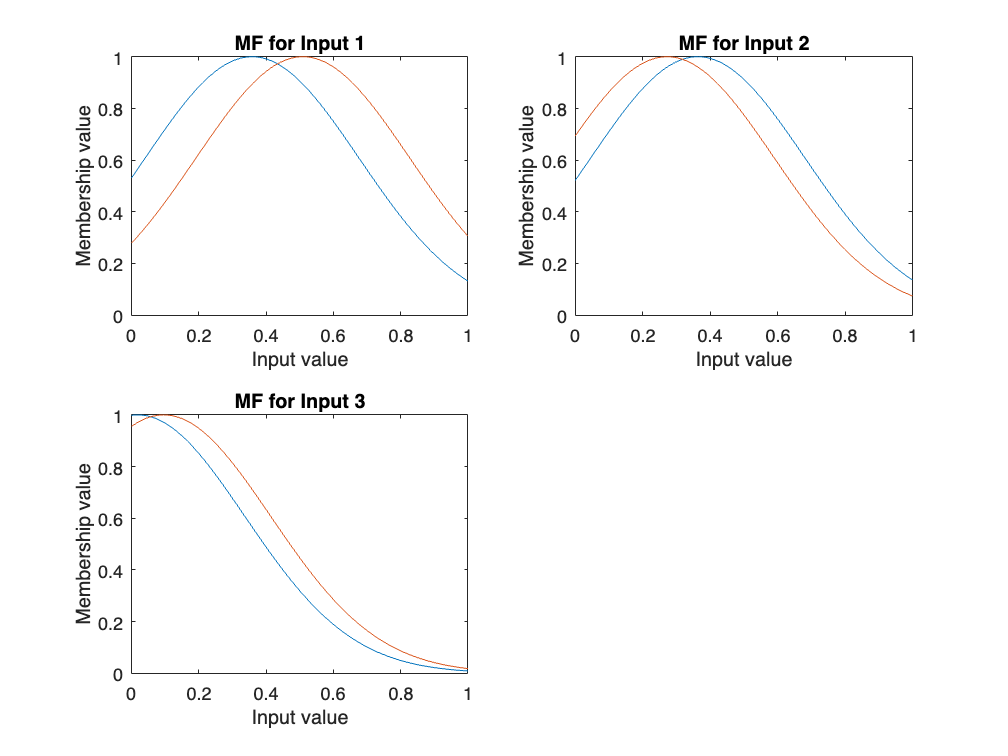

plot_mf(initial_fis_2, 3);

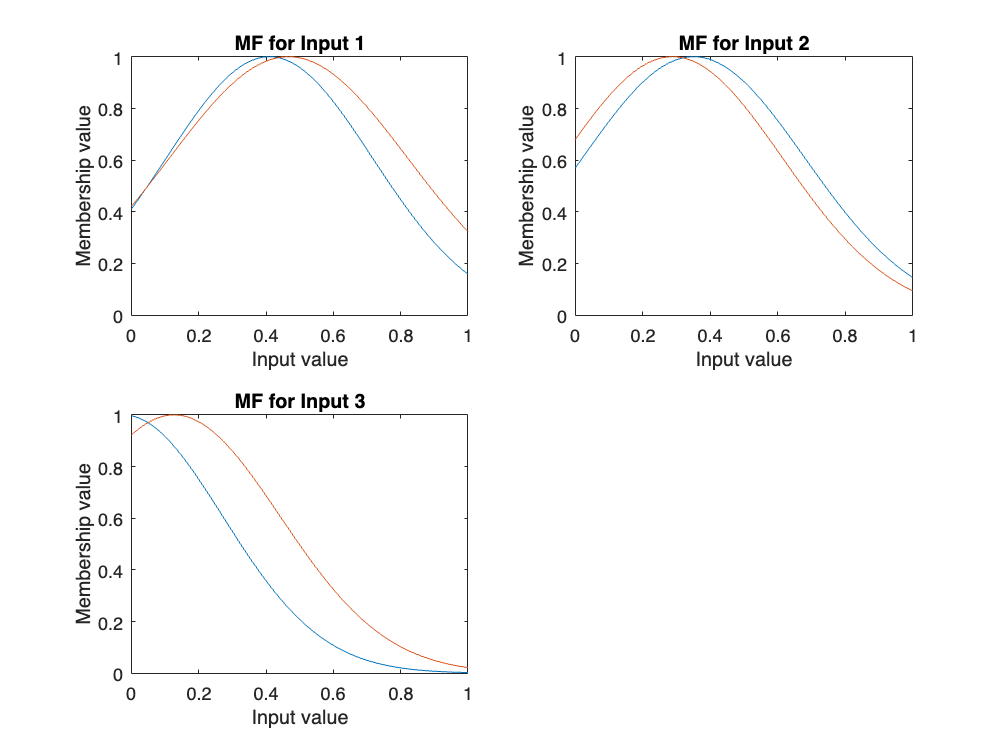

% Train Model 2
tic;
[trained_fis_2, training_info_2] = train_tsk_model(initial_fis_2, Dtrn_1, Dval_1, 100);
time_2 = toc;
plot_mf(trained_fis_2, 3);

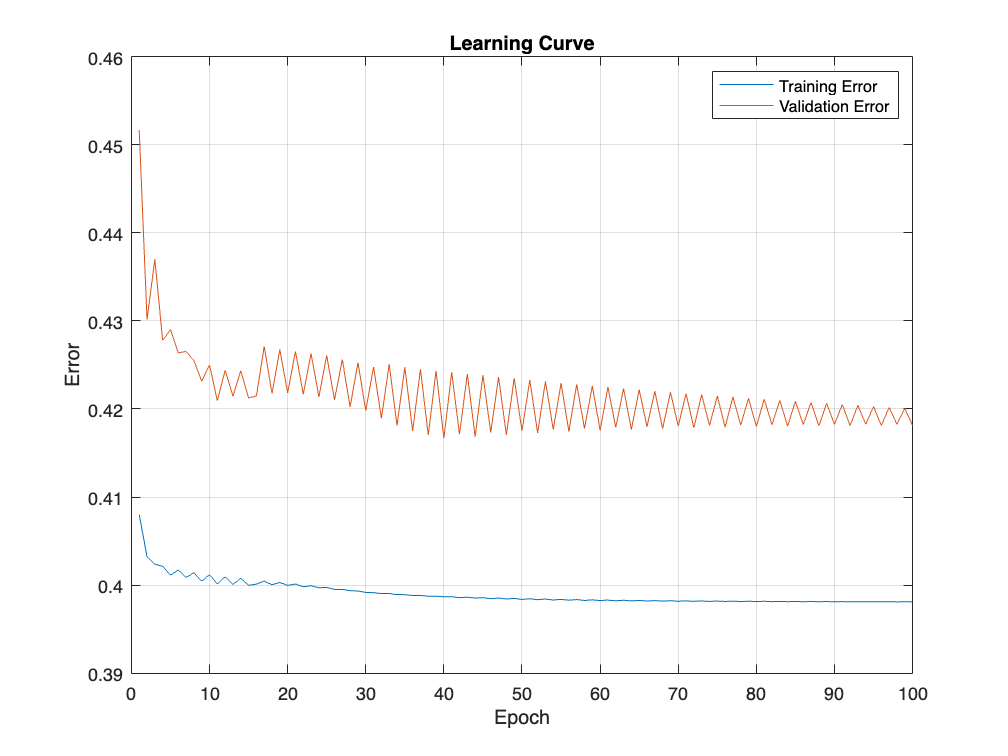

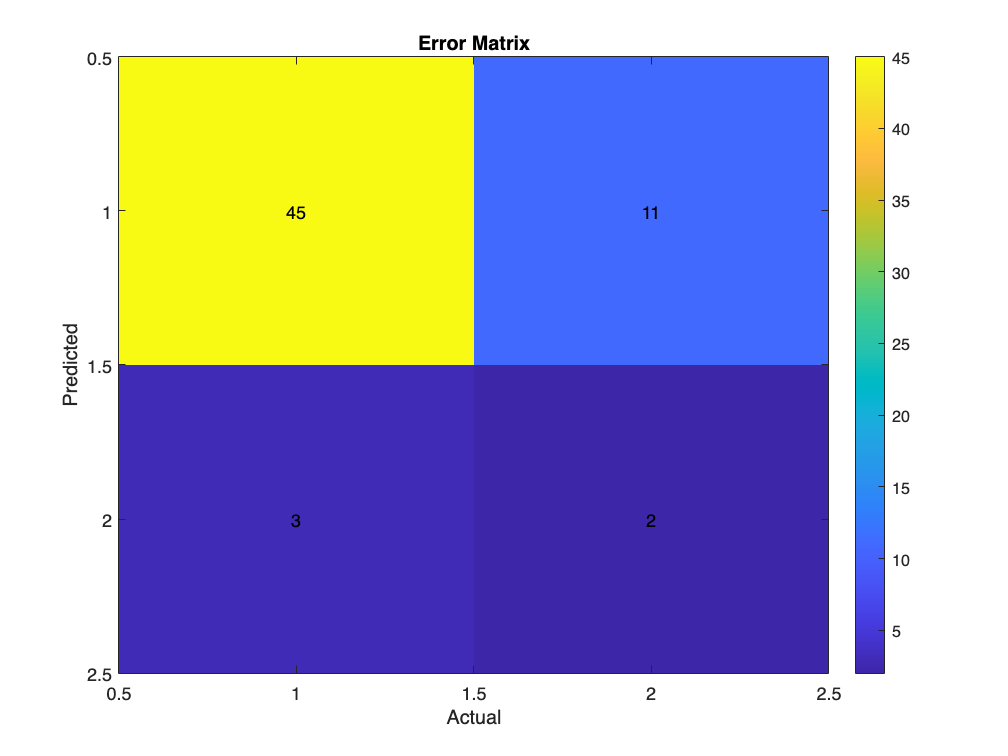

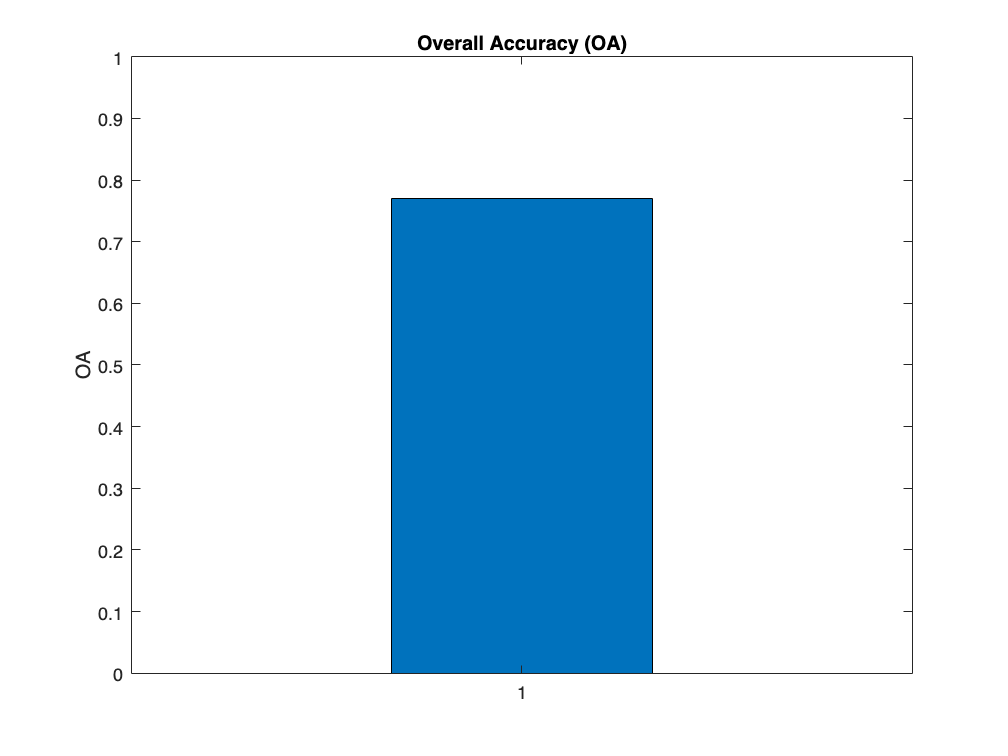

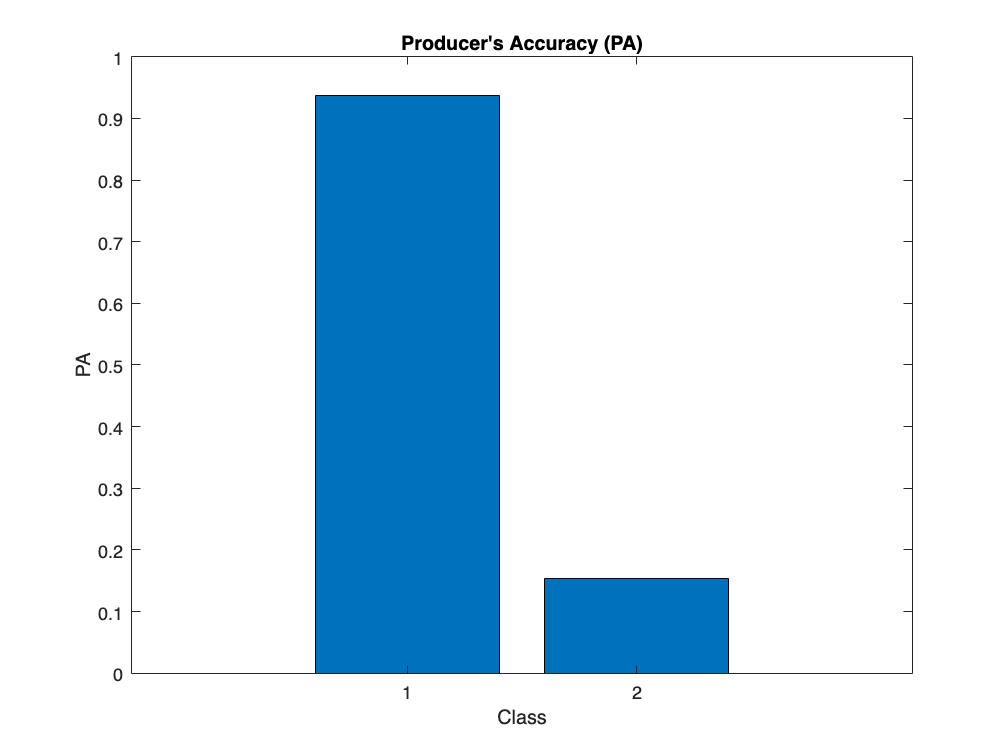

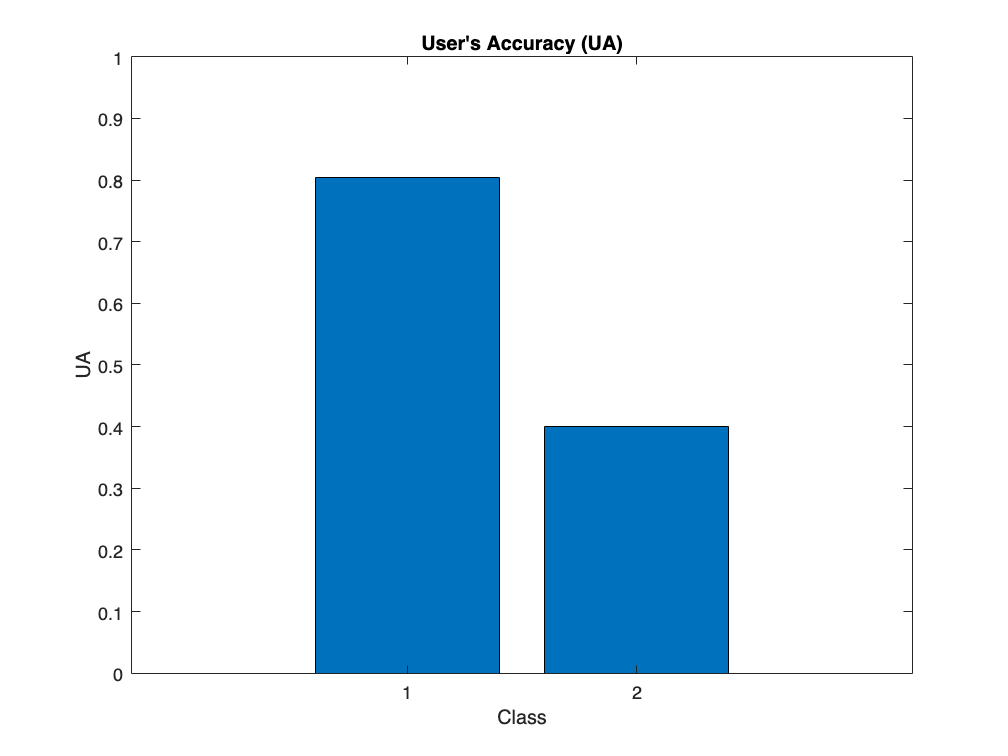

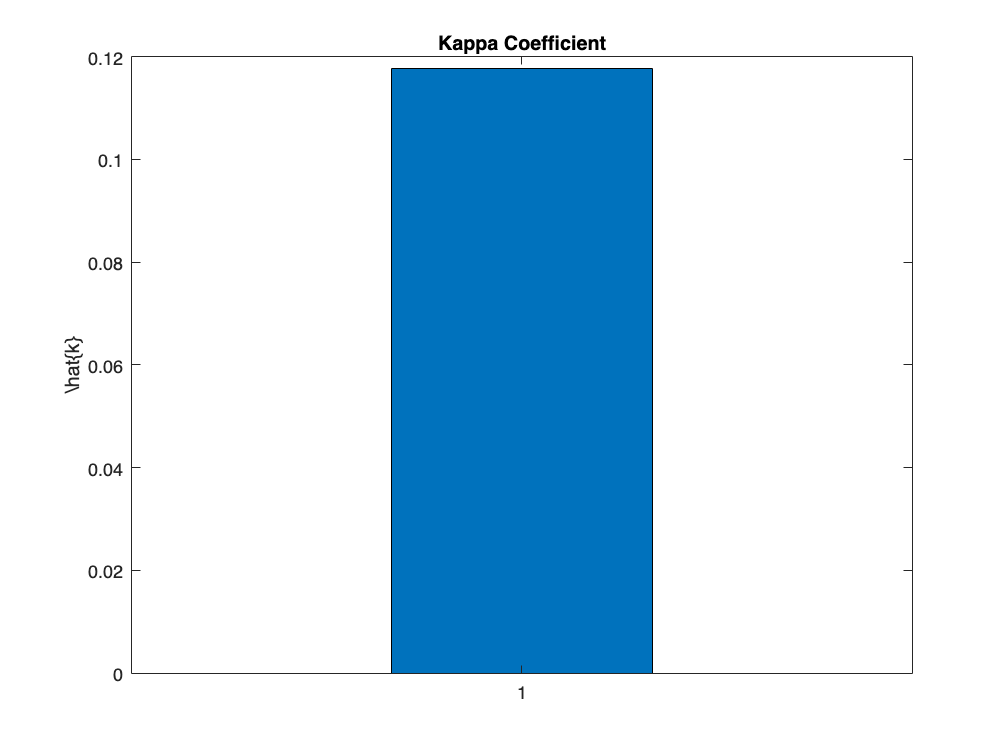

% Evaluate Model 2
[error_matrix, OA, PA, UA, kappa] = metrics_evaluation(trained_fis_2, Dchk_1);
plot_metrics(error_matrix, OA, PA, UA, kappa, training_info_2.trainError, training_info_2.chkError);

model_2_metrics = [OA; max(PA); max(UA); kappa; length(trained_fis_2.Rules)];
fprintf('Classification metrics for the model:\n OA: %.4f, PA: %.4f, UA: %.4f, Kappa: %.4f\n', OA, max(PA), max(UA), kappa);

Classification metrics for the model:
 OA: 0.7705, PA: 0.9375, UA: 0.8036, Kappa: 0.1178


### TSK Model 3

% Define configuration for Model 3
model_3 = struct('Type', 'Dependent', 'Radius', 0.2, 'Part', 1);

initial_fis_3 = initialize_tsk_model(Dtrn_1, model_3);

initial_fis =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×50 fisrule]

	See 'getTunableSettings' method for parameter optimization.


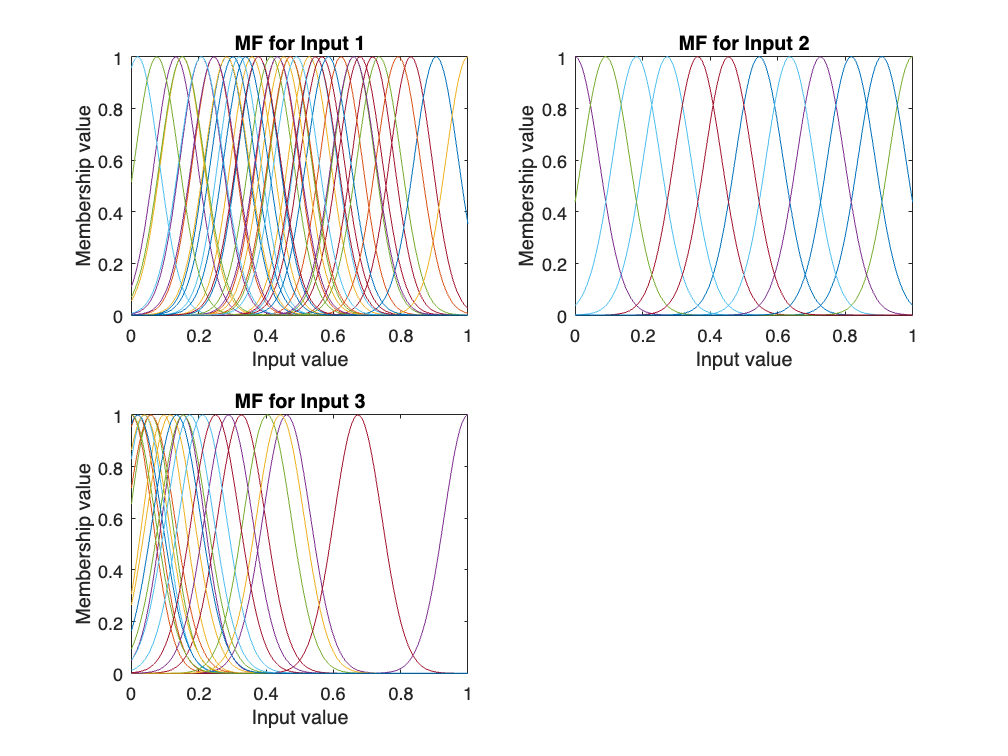

plot_mf(initial_fis_3, 3);

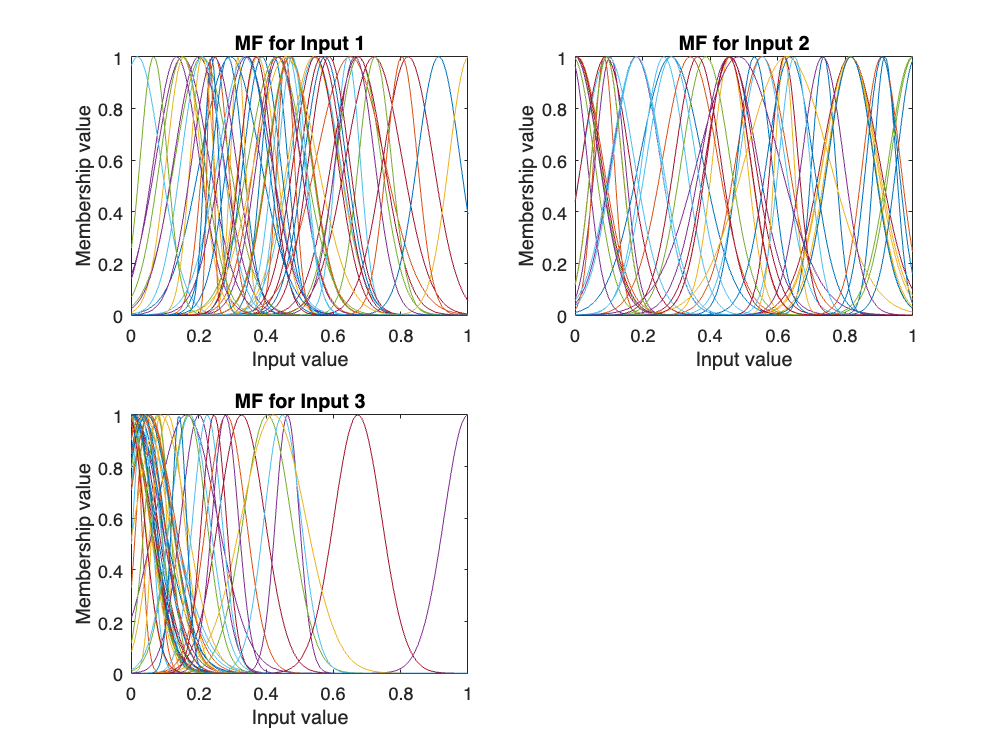

% Train Model 3
tic;
[trained_fis_3, training_info_3] = train_tsk_model(initial_fis_3, Dtrn_1, Dval_1, 100);
time_3 = toc;
plot_mf(trained_fis_3, 3);

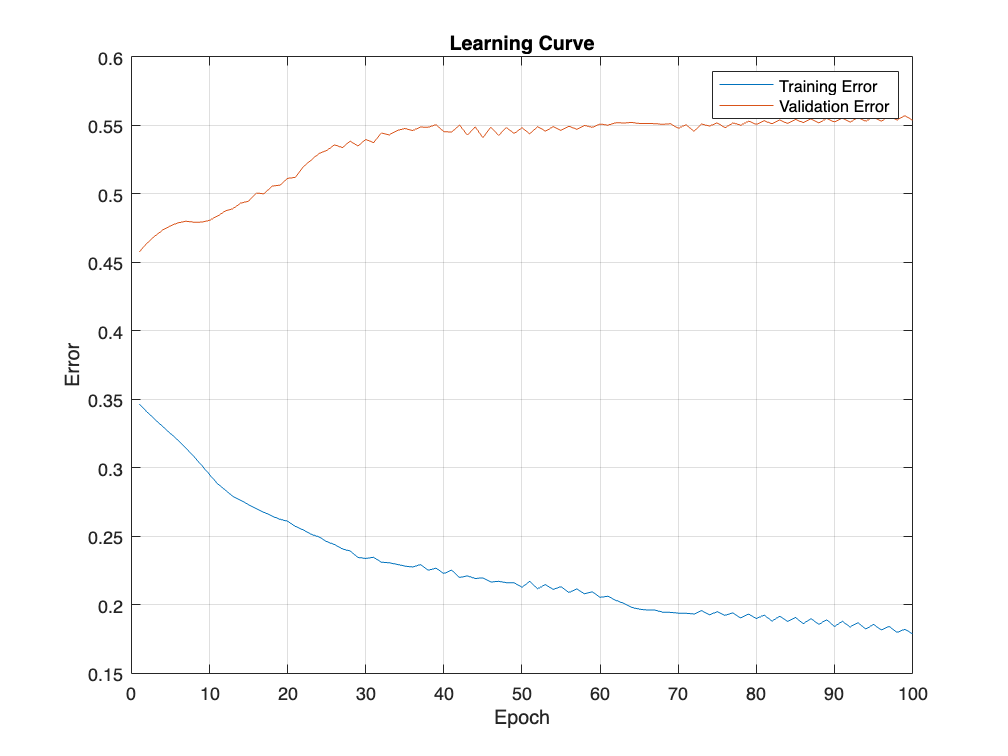

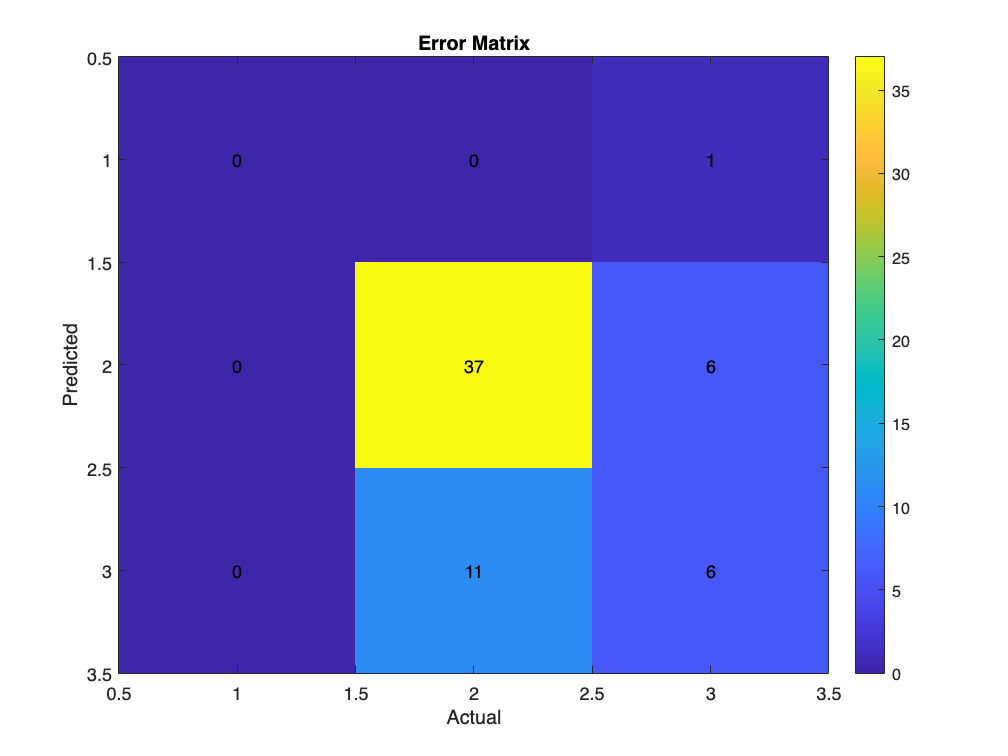

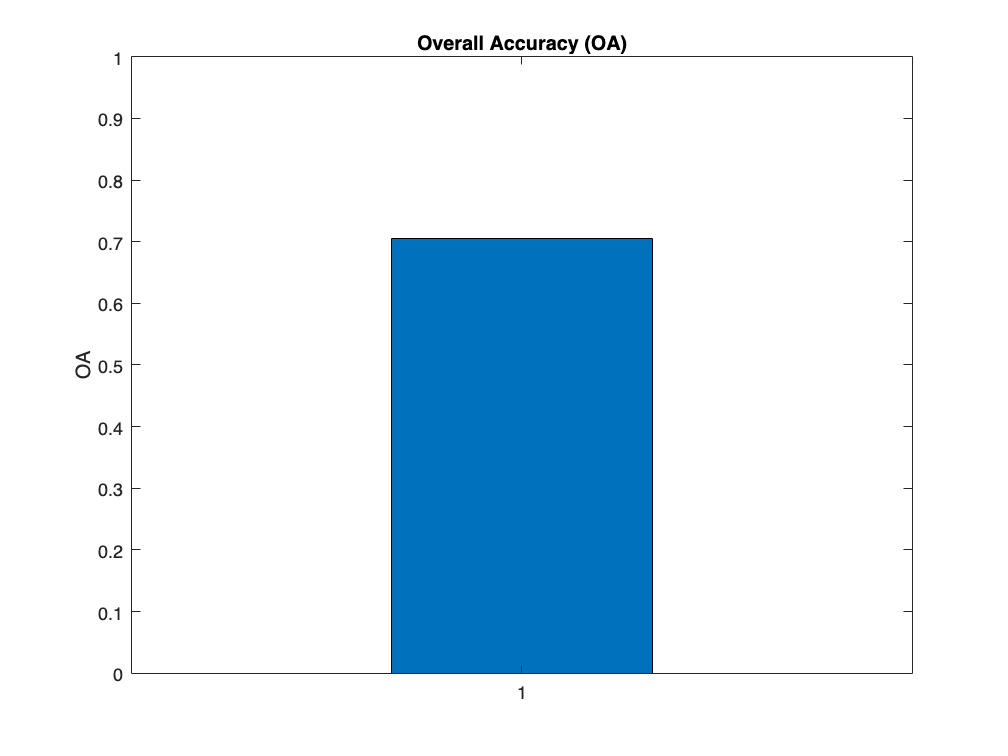

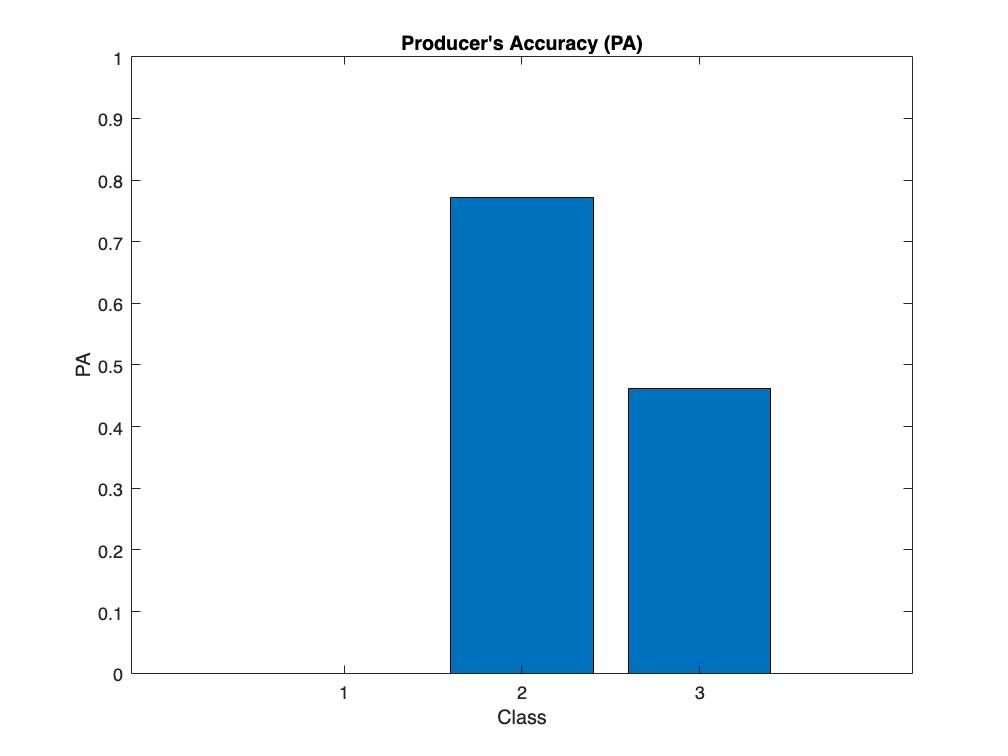

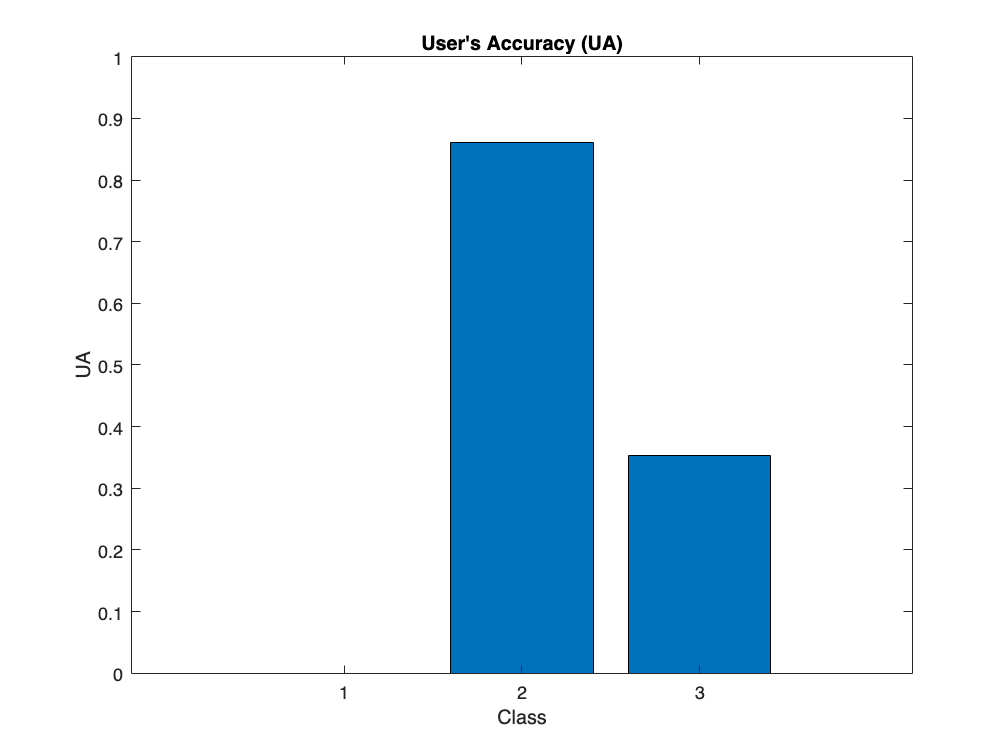

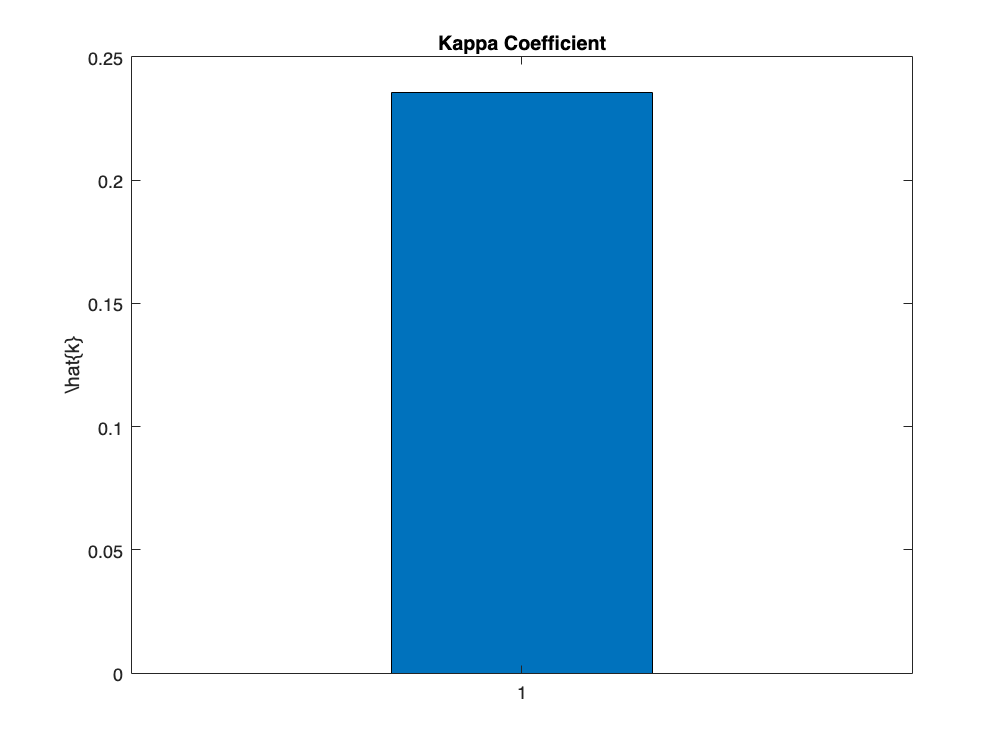

% Evaluate Model 3
[error_matrix, OA, PA, UA, kappa] = metrics_evaluation(trained_fis_3, Dchk_1);
plot_metrics(error_matrix, OA, PA, UA, kappa, training_info_3.trainError, training_info_3.chkError);

model_3_metrics = [OA; max(PA); max(UA); kappa; length(trained_fis_3.Rules)];
fprintf('Classification metrics for the model:\n OA: %.4f, PA: %.4f, UA: %.4f, Kappa: %.4f\n', OA, max(PA), max(UA), kappa);

Classification metrics for the model:
 OA: 0.7049, PA: 0.7708, UA: 0.8605, Kappa: 0.2354


### TSK Model 4

% Define configuration for Model 4
model_4 = struct('Type', 'Dependent', 'Radius', 0.9, 'Part', 1);

initial_fis_4 = initialize_tsk_model(Dtrn_1, model_4);

initial_fis =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×3 fisrule]

	See 'getTunableSettings' method for parameter optimization.


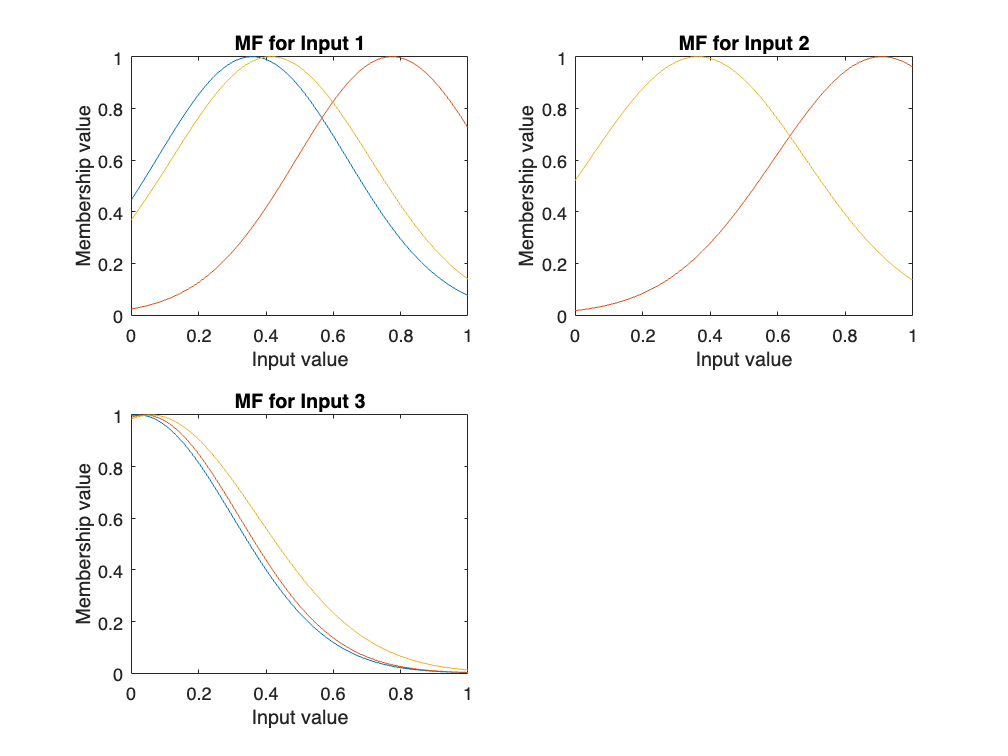

plot_mf(initial_fis_4, 3);

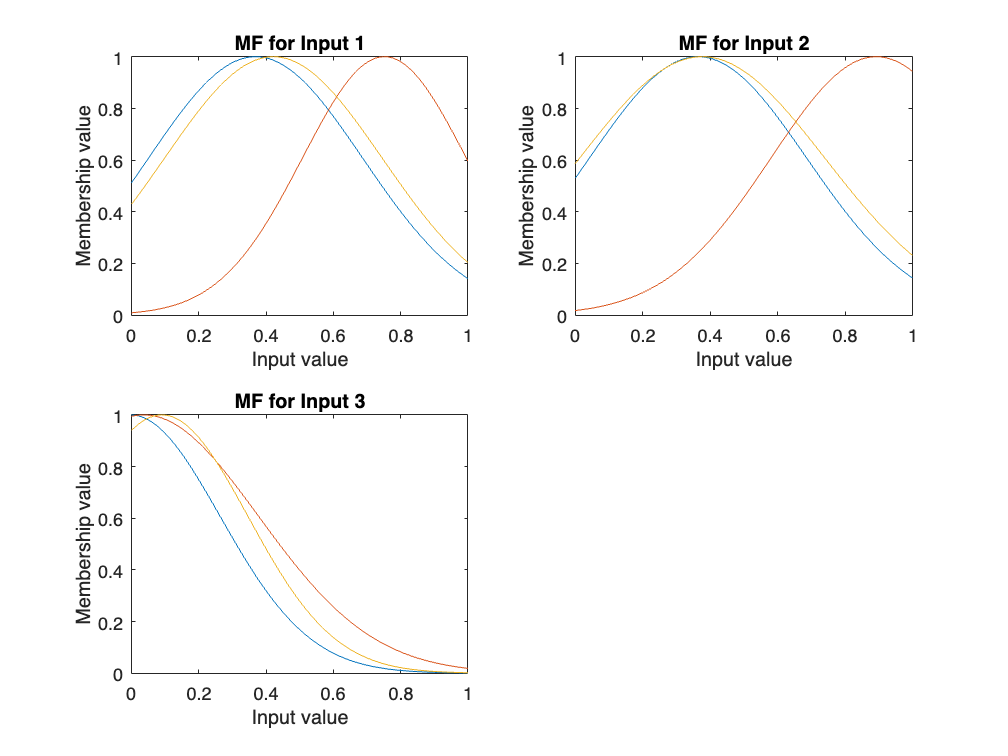

% Train Model 4
tic;
[trained_fis_4, training_info_4] = train_tsk_model(initial_fis_4, Dtrn_1, Dval_1, 100);
time_4 = toc;
plot_mf(trained_fis_4, 3);

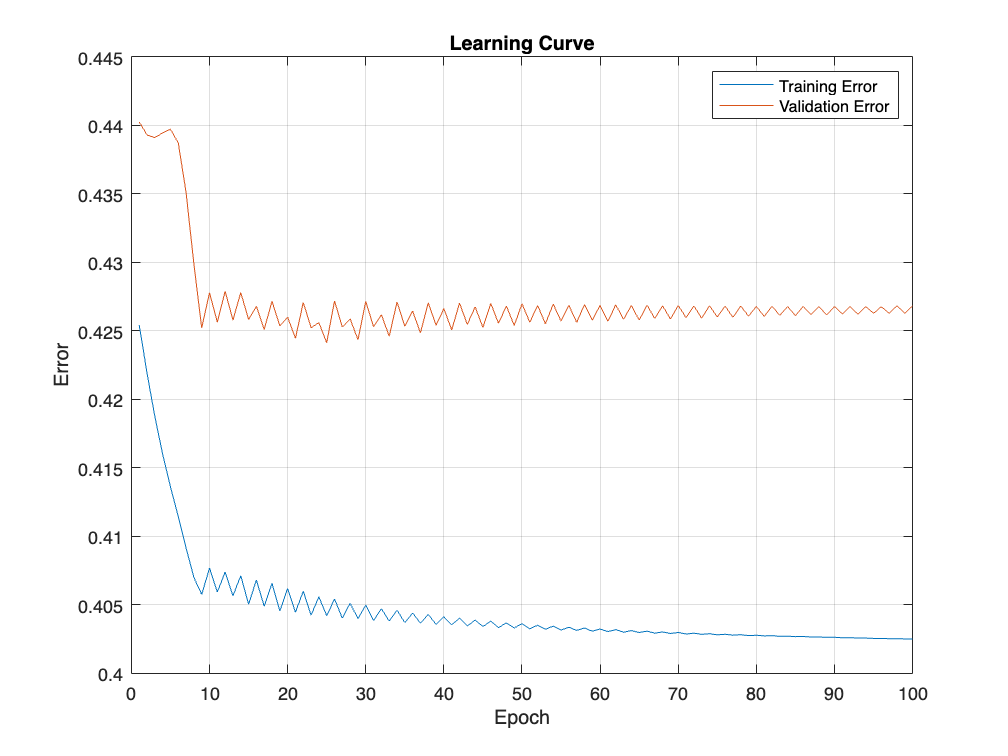

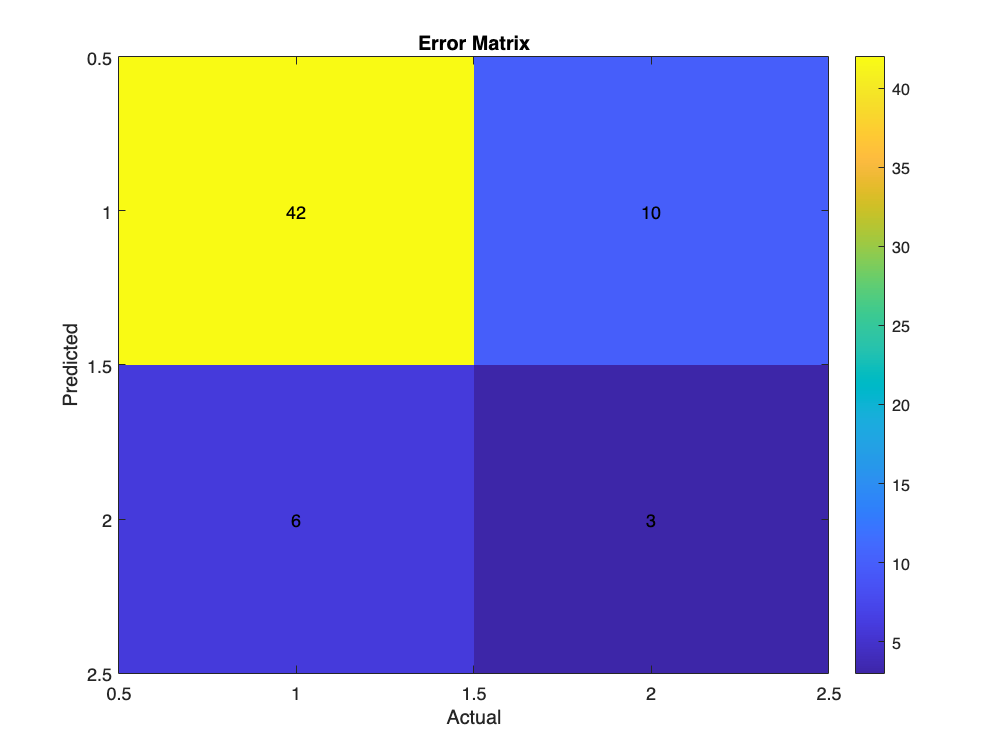

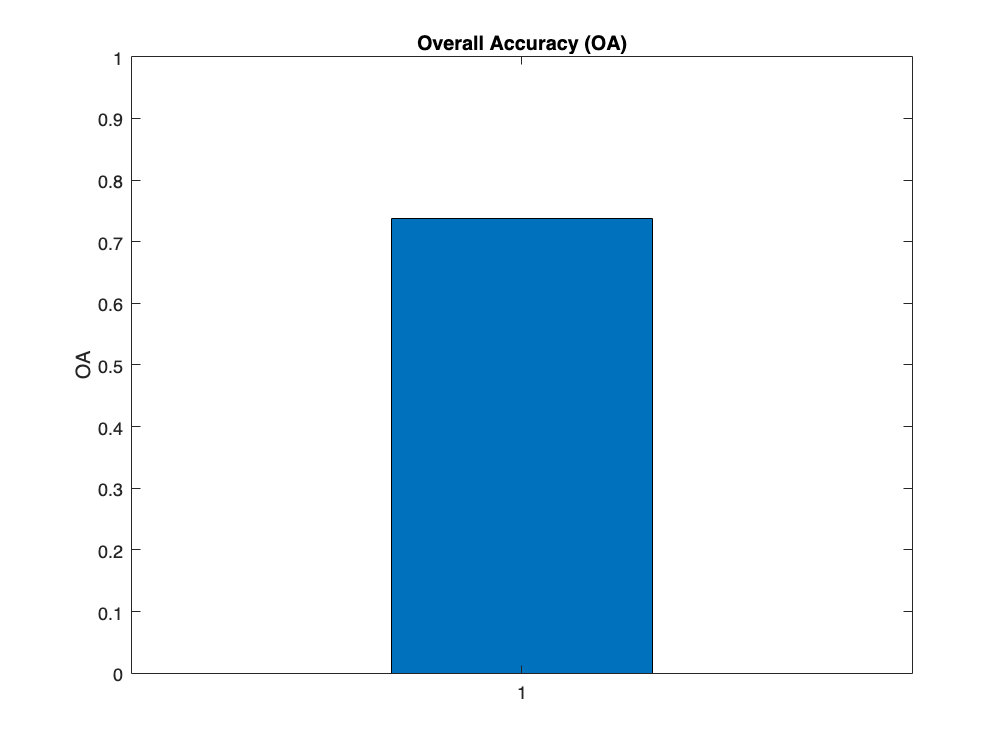

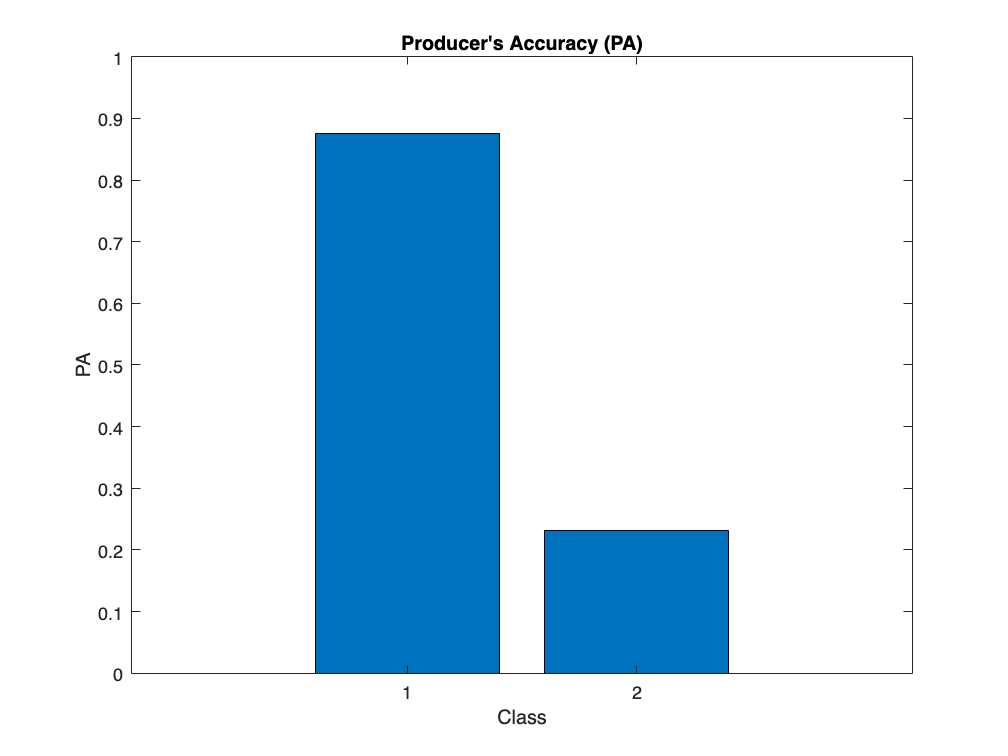

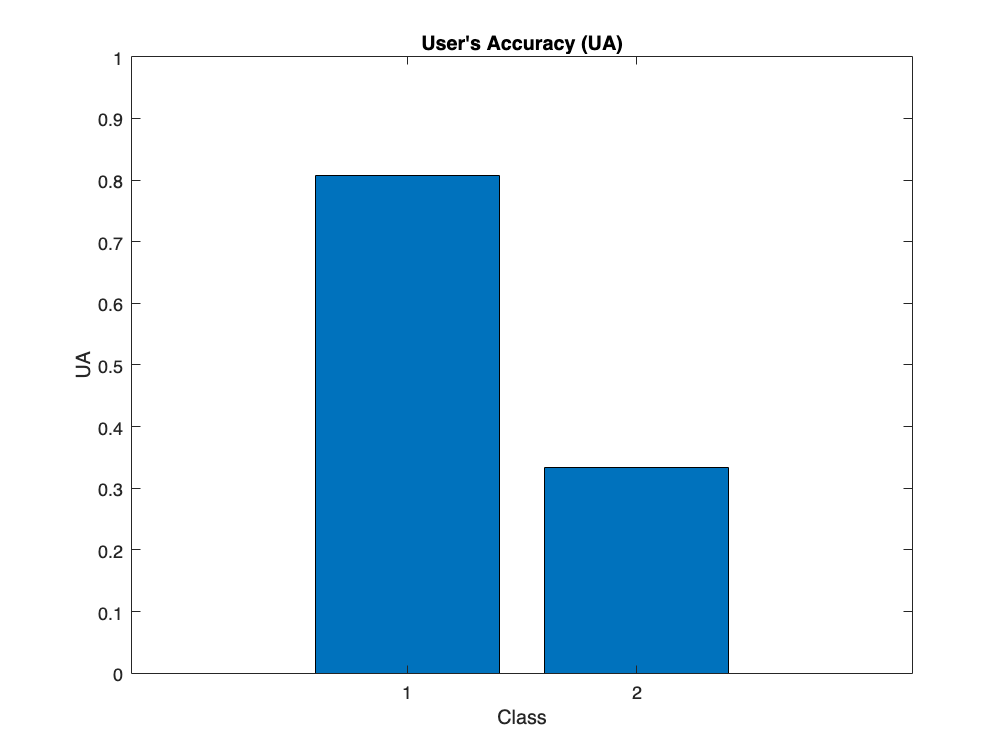

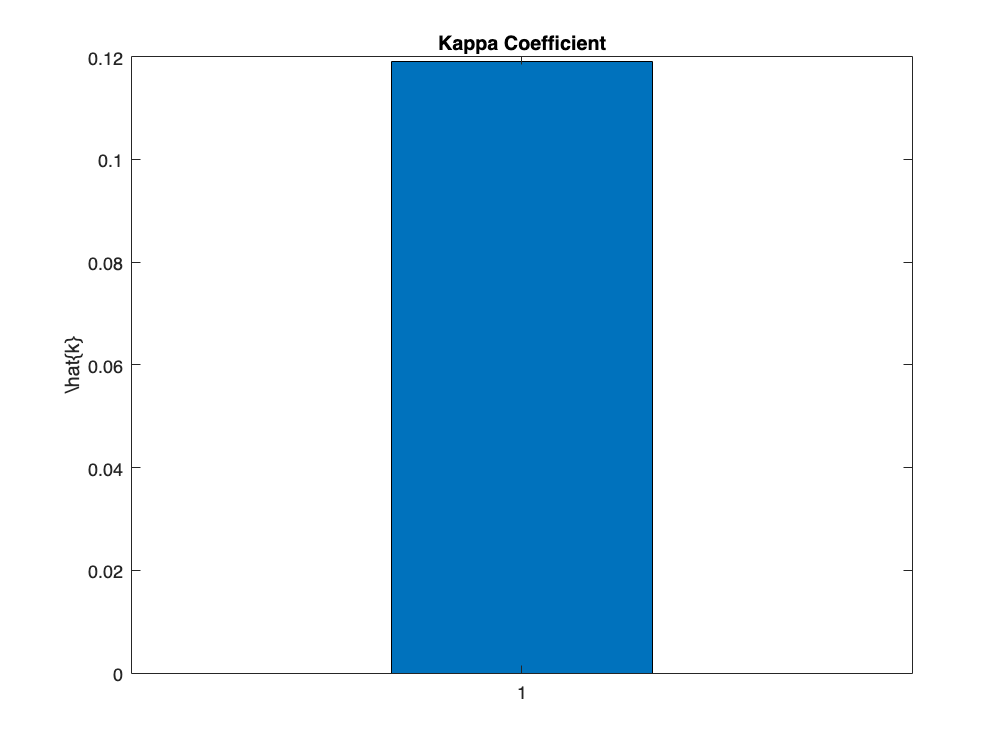

% Evaluate Model 4
[error_matrix, OA, PA, UA, kappa] = metrics_evaluation(trained_fis_4, Dchk_1);
plot_metrics(error_matrix, OA, PA, UA, kappa, training_info_4.trainError, training_info_4.chkError);

model_4_metrics = [OA; max(PA); max(UA); kappa; length(trained_fis_4.Rules)];
fprintf('Classification metrics for the model:\n OA: %.4f, PA: %.4f, UA: %.4f, Kappa: %.4f\n', OA, max(PA), max(UA), kappa);

Classification metrics for the model:
 OA: 0.7377, PA: 0.8750, UA: 0.8077, Kappa: 0.1191


### Comments and Results

Below we can see the comparison of the 4 models in regard to the evaluating metrics, as well as the number of rules

Metrics = {'OA'; 'PA'; 'UA'; 'Kappa'; 'No. of Rules'};
EvalTable = table(Metrics, model_1_metrics, model_2_metrics, model_3_metrics, model_4_metrics);
disp(EvalTable);

        Metrics         model_1_metrics    model_2_metrics    model_3_metrics    model_4_metrics
    ________________    _______________    _______________    _______________    _______________

    {'OA'          }        0.60656            0.77049            0.70492             0.7377    
    {'PA'          }        0.66667             0.9375            0.77083              0.875    
    {'UA'          }        0.86486            0.80357            0.86047            0.80769    
    {'Kappa'       }        0.18167            0.11777            0.23538            0.11913    
    {'No. of Rules'}             26                  2                 50                  3    



Based on the results above, we observe that model 2, which is class independent with a radius of 0.9, offers the best performance overall. Closely following is model 4, class dependent and also with a radius of 0.9. This establishes that a 'looser' radius does not necessarily lead to a drop in performance. Furthermore, class dependency doesn't significantly impact efficacy; both class dependent and independent models yield similar results with a radius of 0.9.

When we examine the role of rules, fewer seem to contribute to better performance. Model 2 and Model 4, each having only 2 and 3 rules respectively, outperform the other models on OA and PA by a lot, whereas in UA and Kappa, the difference is not significant. This challenges the conventional notion that more rules automatically yield better classification and suggests that fewer rules may improve the model's ability to generalize to unseen data.

Moving on to models with a 'tighter' radius of 0.2, performance struggles are evident. Model 1, with 26 rules, and Model 3, with 50, both exhibit lower metrics. Intriguingly, when a small radius is paired with class dependency, as in Model 3, not only does the number of rules surge but the Kappa value, even though it increases, it remains low enough to not justify any real impact. This implies that such a model's accuracy may be largely by chance, raising concerns about their reliability in prediction.

In conclusion, in our case, maintaining a looser radius appears to be the most critical factor, enhancing generalization and overall model performance.

Examining the learning curves, we can see that they further support our findings and the models' performance. Model 1's curve shows a steady divergence, an observation consistent with its general performance, as the worst performer overall. Model 2, demonstrating early stabilization and small error gap, complements its position as the top performer. Model 3's rising validation errors echo the potential overfitting concerns, but the gap is not as significant as the first model's, and justifies the metrics as a solid choice. Model 4's early convergence and the small gap between training and validation error, verifies its top placement in our evaluations, as a very close second.

In terms of rule activation and overall performance, models with a larger radius tend to do better. A larger radius likely allows for more overlap in fuzzy set projections on the inputs, making the model more flexible and effective. In contrast, a smaller radius restricts this overlap, resulting in poorer performance, as seen in Model 1 and Model 3.

In light of the data, fine-tuning the radius seems crucial for performance. A reduced rule set also shows promise for better outcomes. Balancing class dependency and compute time could further help model selection.

Finally below, we observe the time it took for each model to train. Fewer rules clearly correlate with less training time, as seen in Model 2 and Model 4. Model 1 and Model 3, with more rules, require more time. Class dependency doesn't appear to affect training time significantly. For instance, Model 1 takes less time than Model 3, and Model 4 takes less time than Model 2, even though they differ only in class dependency.

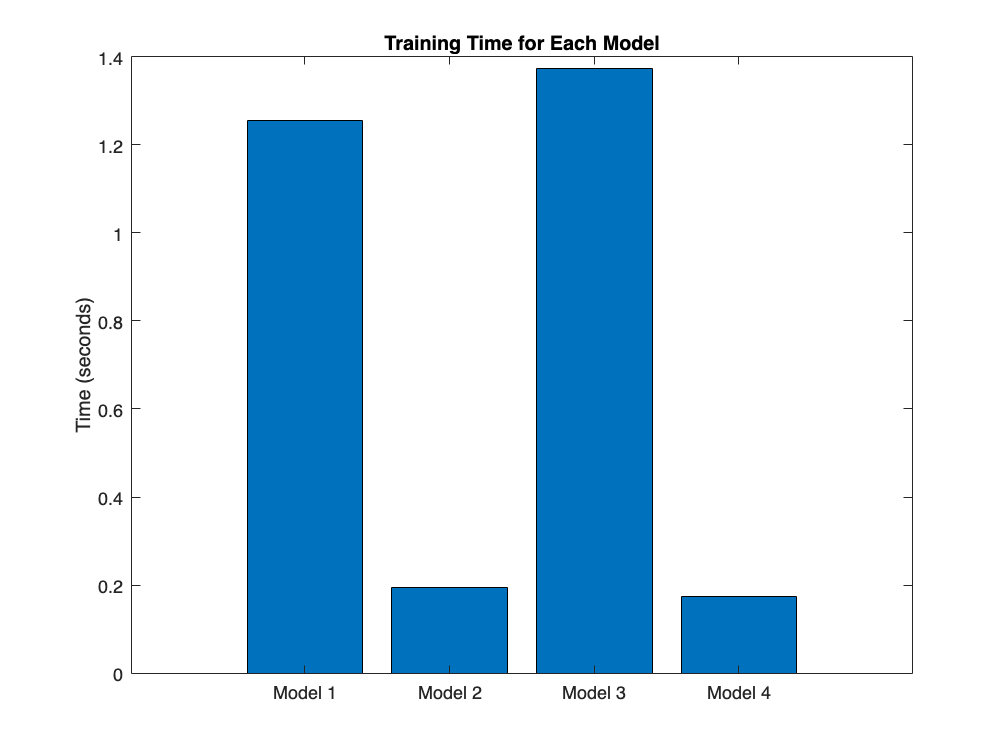

% Create a bar graph for training times
figure;
bar([time_1, time_2, time_3, time_4]);
xticklabels({'Model 1', 'Model 2', 'Model 3', 'Model 4'});
ylabel('Time (seconds)');
title('Training Time for Each Model');